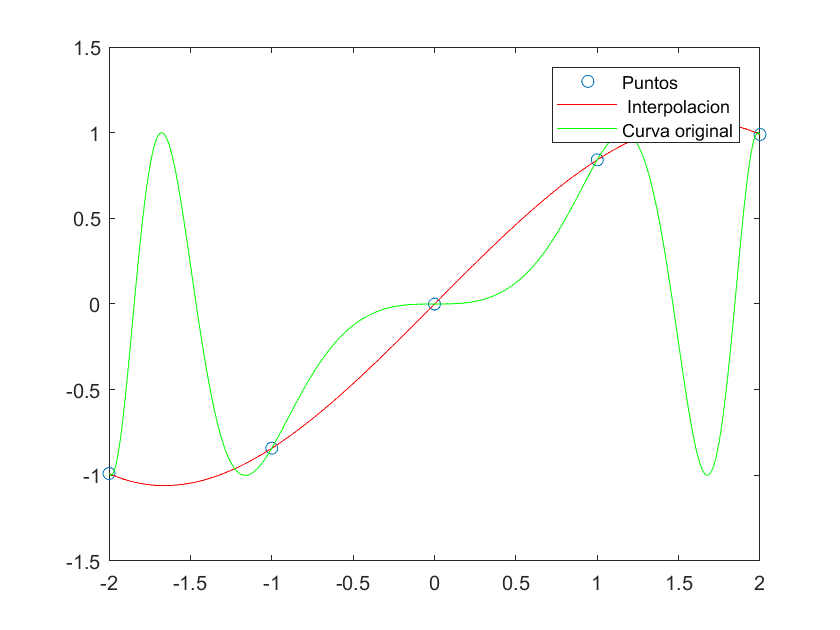

x = -2:1:2;
y = sin (x.^3);
figure;
plot (x,y,'o'); hold on
t = -2:0.01:2;
plot(t,polyinterp(x,y,t),'r');
plot(t,sin(t.^3),'g');
legend('Puntos ',' Interpolacion ','Curva original ');

Ejemplos

1. Cálculo y gráfica de un polinomio interpolante con polyinterp 

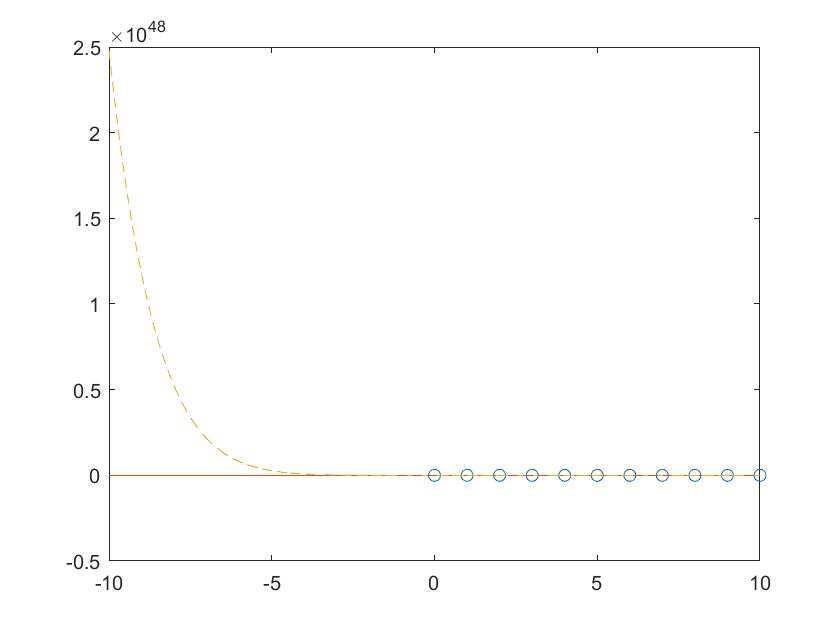

x=0:1:10;
y=exp(x.^2);
t=-10:0.01:10;
v=polyinterp(x,y,t);
figure;
plot(x,y,'o',t,exp(t.^2),'-',t,v,'--');

2. Cálculo de los coeficientes de un polinomio con vander

x=1:10;
y=sin(x.^2);
coef=vander(x).\y

coef =     0.8415   -0.7568    0.4121   -0.2879   -0.1324   -0.9918   -0.9538    0.9200   -0.6299   -0.5064
    0.0016   -0.0030    0.0032   -0.0045   -0.0041   -0.0620   -0.1192    0.2300   -0.3149   -0.5064
    0.0000   -0.0001    0.0002   -0.0004   -0.0005   -0.0122   -0.0353    0.1022   -0.2100   -0.5064
    0.0000   -0.0000    0.0000   -0.0001   -0.0001   -0.0039   -0.0149    0.0575   -0.1575   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0016   -0.0076    0.0368   -0.1260   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0008   -0.0044    0.0256   -0.1050   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0028    0.0188   -0.0900   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0019    0.0144   -0.0787   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0013    0.0114   -0.0700   -0.5064
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0010    0.0092   -

3. Gráfica de un spline con spline.

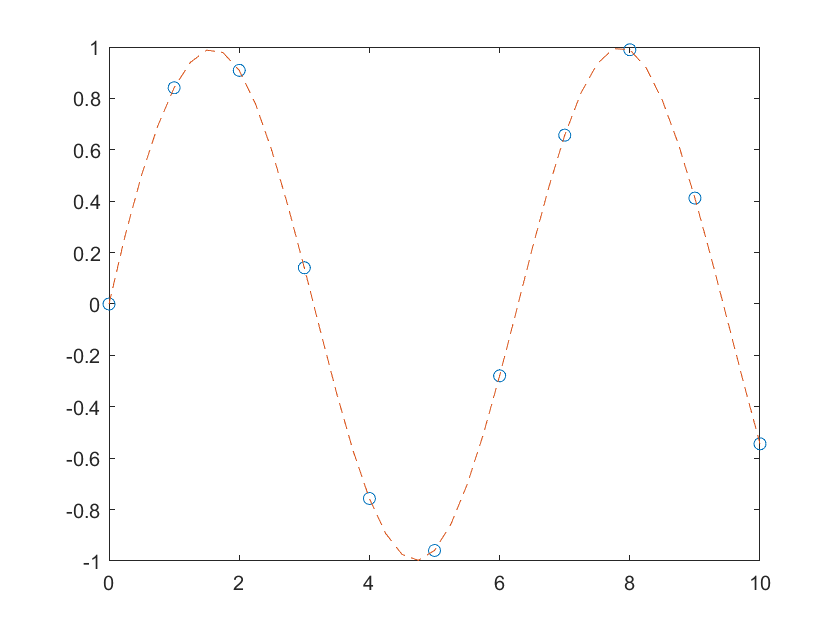

x = 0:10;
y = sin(x);
xx = 0:.25:10;
yy = spline(x,y,xx);
plot(x,y,'o',xx,yy,'--')

Ajuste de curvas por mínimos cuadrados

clear all
t =[10 20 30 40 50 60 70 80];
y =[1.06 1.33 1.52 1.68 1.81 1.91 2.01 2.11];

p = polyfit(t,log(y),1); % En Matlab el logaritmo natural es log
fprintf('parametro x_2 = %2.3f\n', p(1));

parametro x_2 = 0.009


fprintf('parametro x_1 = %3.3f\n', exp(p(2)));

parametro x_1 = 1.090


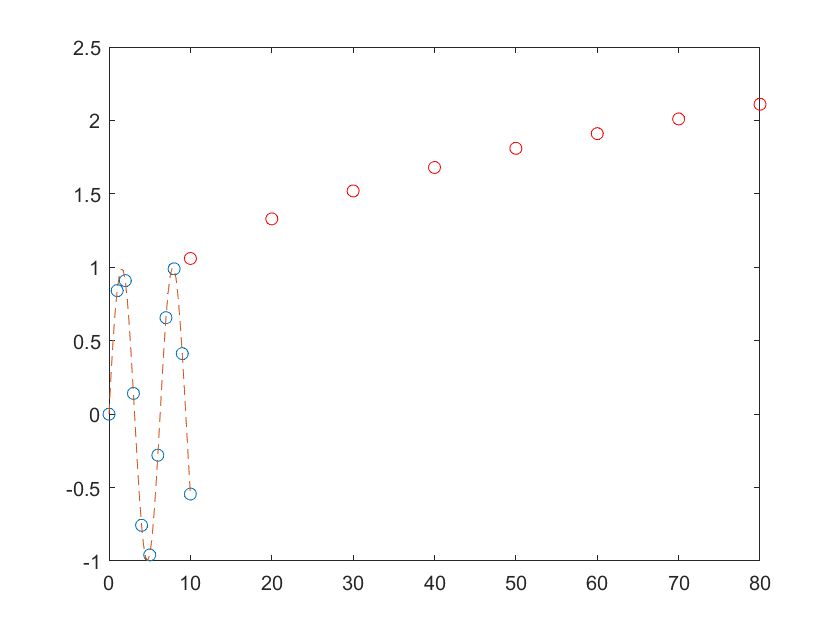

hold on
plot (t,y,'ro')

x = linspace(min(t), max(t), 50);
z = exp(p(2)) * exp(p(1) * t);
plot(x,z,'b')

Error using plot
Vectors must be the same length.

xlabel('x')
ylabel('y')
title('Regresion exponencial ')
hold off
